tim_freq_hz = 40000000;
tsf_freq_hz =  1000000;
samplerate_hz = 100;
chunk_length_s = 1:1:30;
windows_length_s = 60:30:300;
step_window_length = 0.5;

# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 22-Feb-2025 14:42:25

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["tim_timestamp", "tsf_timestamp"];
opts.VariableTypes = ["double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
capture = readtable(".\data\10ms_600s.txt", opts)

capture = 59999×2 table
    tim_timestamp    tsf_timestamp
    _____________    _____________

          14341       8.0405e+12  
      3.941e+05       8.0405e+12  
      7.941e+05       8.0405e+12  
     1.1941e+06       8.0405e+12  
     1.5941e+06       8.0405e+12  
     1.9941e+06       8.0405e+12  
     2.3941e+06       8.0405e+12  
     2.7941e+06       8.0405e+12  
     3.1941e+06       8.0405e+12  
     3.5941e+06       8.0405e+12  
     3.9941e+06       8.0405e+12  
     4.3941e+06       8.0405e+12  
     4.7941e+06       8.0405e+12  
     5.1941e+06       8.0405e+12  
     5.5941e+06       8.0405e+12  
     5.9941e+06       8.0405e+12  


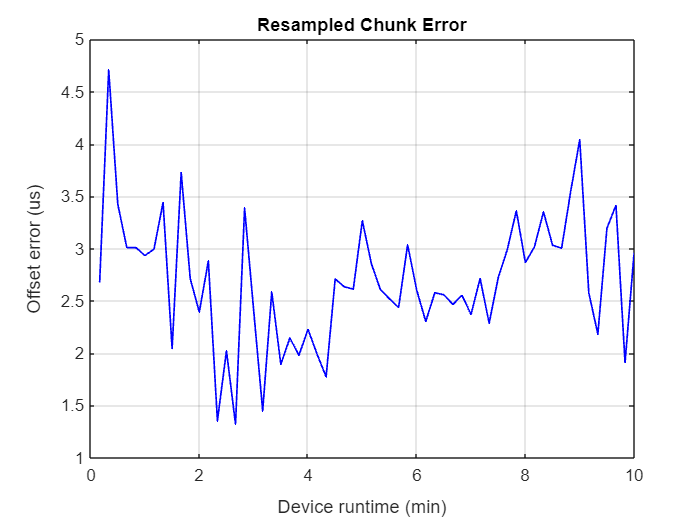


% Calculate timestamps
tim_timestamps_arr = capture.tim_timestamp - capture.tim_timestamp(1);
tsf_timestamps_arr = capture.tsf_timestamp - capture.tsf_timestamp(1);

% Compute linear fit
p = polyfit(tim_timestamps_arr, tsf_timestamps_arr, 1);


tsf_predicted = polyval(p, tim_timestamps_arr);
error_tsf = tsf_predicted - tsf_timestamps_arr - tsf_predicted(1);


capture_time_s = (capture.tim_timestamp(length(capture.tim_timestamp)-1) - capture.tim_timestamp(1))/tim_freq_hz;
new_length = ceil(capture_time_s / 10);
chunks_tttt = 1:1:new_length;
chunks_tttt = (chunks_tttt / length(chunks_tttt)) * capture_time_s / 60;

% Resample data to reduce the number of points
%new_length = floor(length(error_tsf) / factor);
error_resampled = resample(error_tsf, new_length, length(error_tsf));
chunks_resampled = linspace(1, length(error_tsf), new_length);

% Plot the resampled data
figure;
plot(chunks_tttt, error_resampled, 'b-', 'LineWidth', 1);
xlabel('Device runtime (min)');
ylabel('Offset error (us)');
title('Resampled Chunk Error');
grid on;


%clear opts



window_start = 1;

for i = 1:length(windows_length_s)
    window_size_samples = windows_length_s(i) * samplerate_hz;
    for j = 1:(length(tim_timestamps_arr)/window_size_samples)
        chunk_length_samples = j * samplerate_hz;
        disp(j);
        %for k = 1:(length(tim_timestamps_arr))

        %end
        
        window_data = tim_timestamps_arr(window_start:(window_start + window_size_samples - 1));
    end
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

     1

     2

     3

     4

     5

     6

     1

     2

     3

     4

     1

     2

     3

     1

     2

     3

     1

     2

     1

     2

     1

     2

     1




%tim_timestamps_arr = data(offset:(offset + window_size - 1));
%windows_length_s = 